# PID Tuning

## Load data from extrapolation

Data loading of the matrix of Force and Inductance.

load('parameters.mat')
disp(equilibrium(6:8,1:3));

    Cards     Mass     Current
    _____    ______    _______

      6      0.8734     1.109 
      7       0.875     1.179 
      8      0.8766     1.232 



% Position conversion from scope's unit to [m].
scope_positions = positions;
positions = positionConversion(positions);

## Linearization of Force around (x0, i0)

Around the equilibrium position chosen at 8 cards.

% Number of cards and relative position:
ncards=8;
[i0,x0,dfdi,dfdx,F0,dldi,dldx,L0] = equilibriumFeatures(F,LL,current,positions,equilibrium,ncards);
[ifin,xfin,~,~,~,~,~,~] = equilibriumFeatures(F,LL,current,positions,equilibrium,7);
initialConditions = [0;x0;i0]

initialConditions =          0
    0.0099
    1.2320


target = [0;xfin;ifin]

target =          0
    0.0105
    1.1790


% System matrix definition
[A, B, C, D] = magnetABCD(current, positions, F, LL, i0, x0)

A = 	1.0e+03 *

         0    1.7057    0.0158
    0.0010         0         0
         0         0   -0.0239


B =          0
         0
    5.8270


C =      0     1     0
     0     0     1


D =      0
     0


PolesUC = eig(A);

## Transfer function

ltiSys = ss(A,B,C,D);

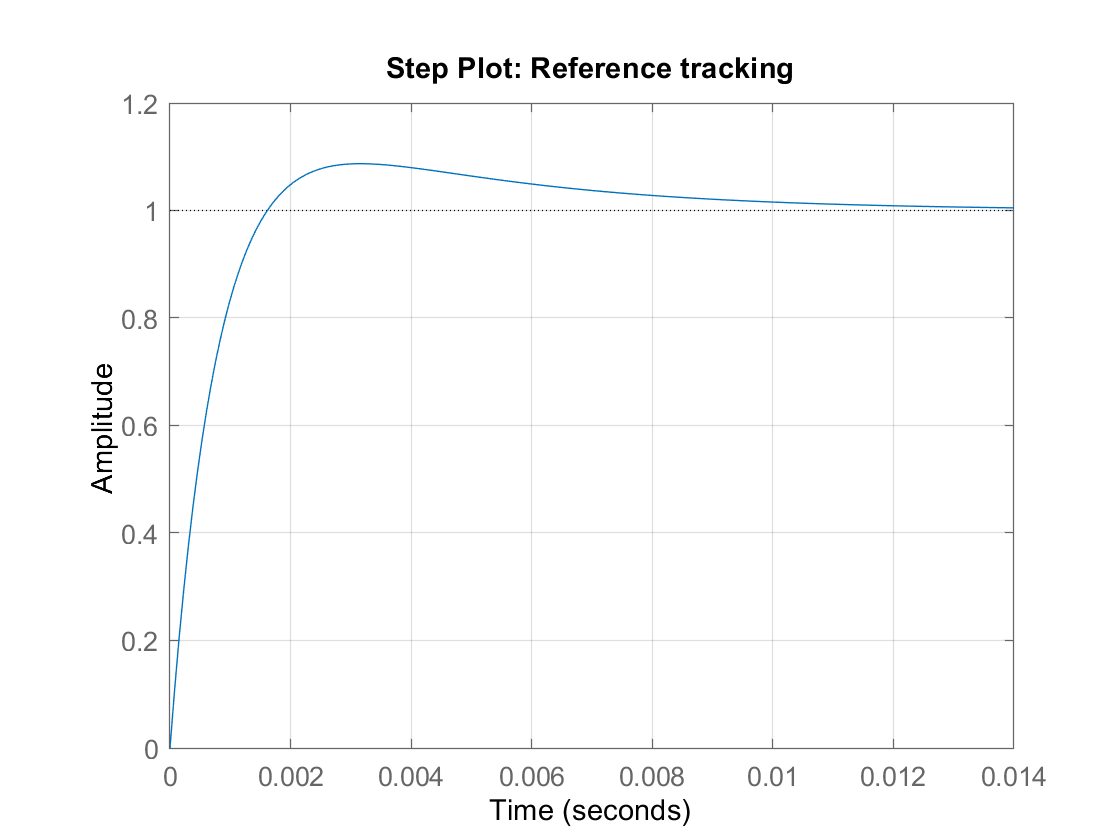

% Define options for pidtune command
opts = pidtuneOptions('PhaseMargin',81.9335);

% PID tuning algorithm for linear plant model
[C2,pidInfo] = pidtune(E,'PI',1507.19,opts);

% Clear Temporary Variables
clear opts

% Get desired loop response
Response = getPIDLoopResponse(C2,E,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Clear Temporary Variables
clear Response

pidInfo

pidInfo = struct with fields:
                Stable: 1
    CrossoverFrequency: 1600
           PhaseMargin: 81.9335


C2

C2 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 271, Ki = 6.81e+04
 
Continuous-time PI controller in parallel form.




o = tf(ltiSys)

o =
 
  From input to output...
                      92.3
   1:  -----------------------------------
       s^3 + 23.89 s^2 - 1706 s - 4.075e04
 
         5.827
   2:  ---------
       s + 23.89
 
Continuous-time transfer function.



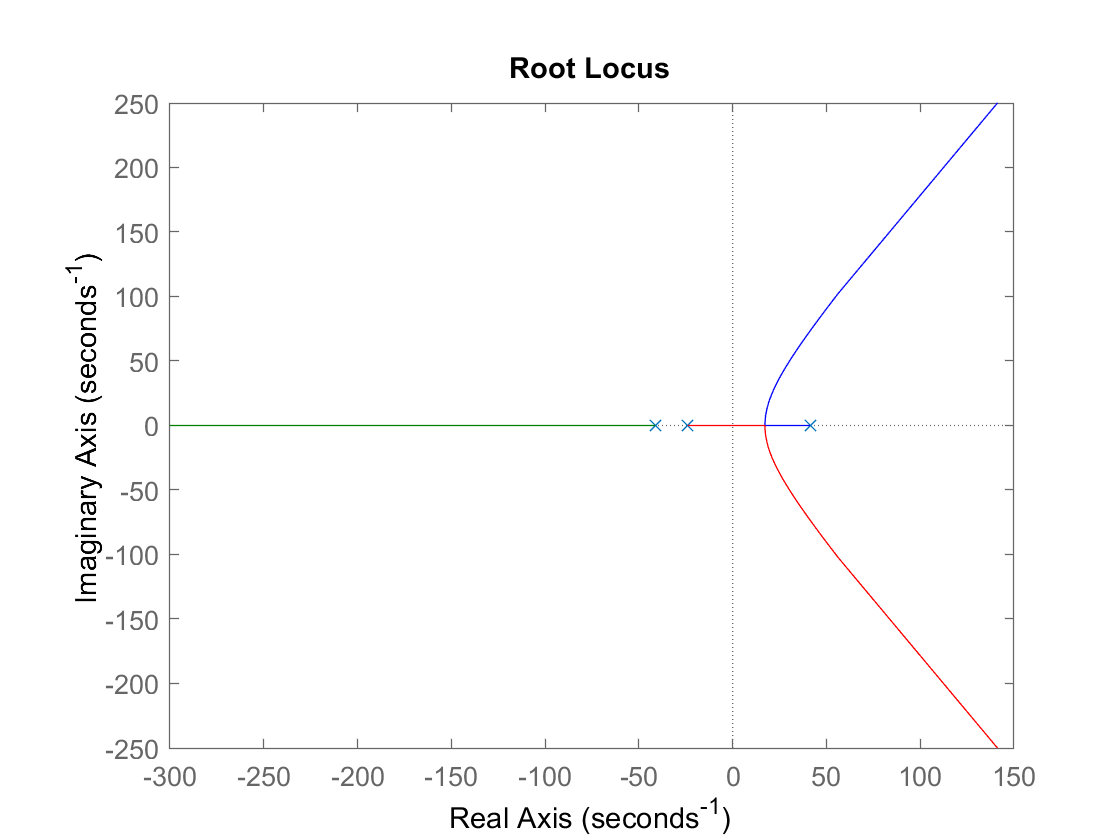

Error using DynamicSystem/pidtune (line 105)
The first input argument of the "pidtune" command must be a single-input, single-output linear plant model.

Resist = 4.1;

s = tf('s');
rlocus(o(1))